# s_figuresEI2021

Figures for the Cornell Box presentation at EI 2021.

ieInit;

## Horizontal line selection

Read in the simulated and real MCC sensor data that Zheng provided.  Crop them down for ease of plotting.  The extract the position and values for alignment.

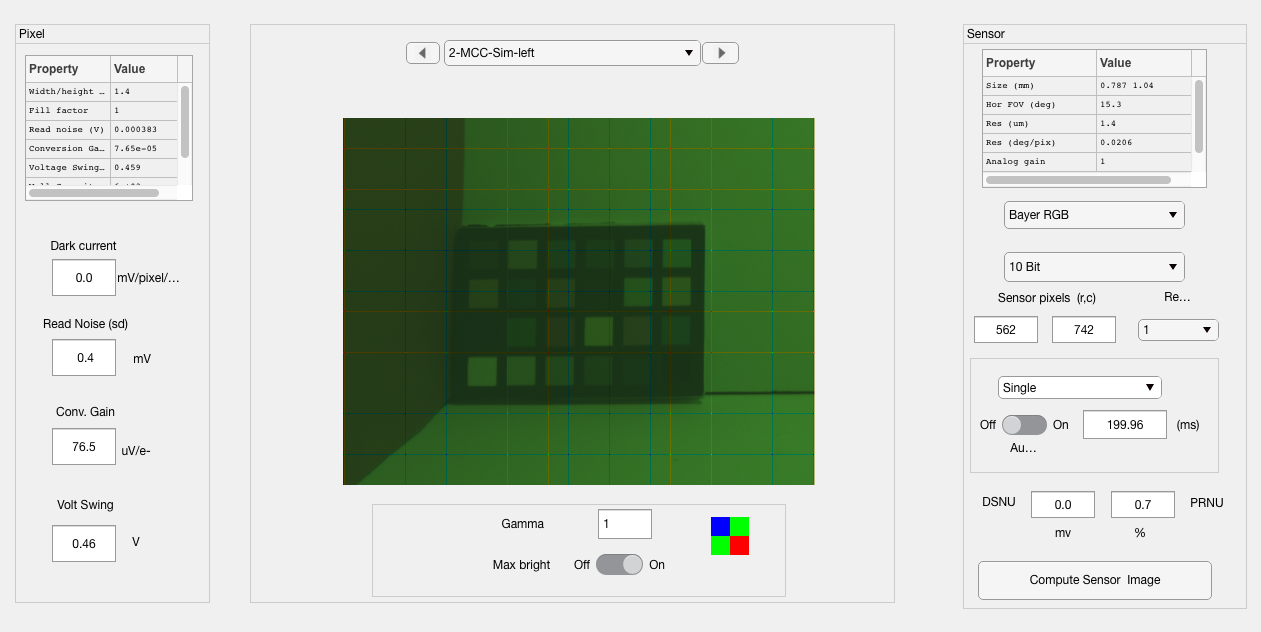

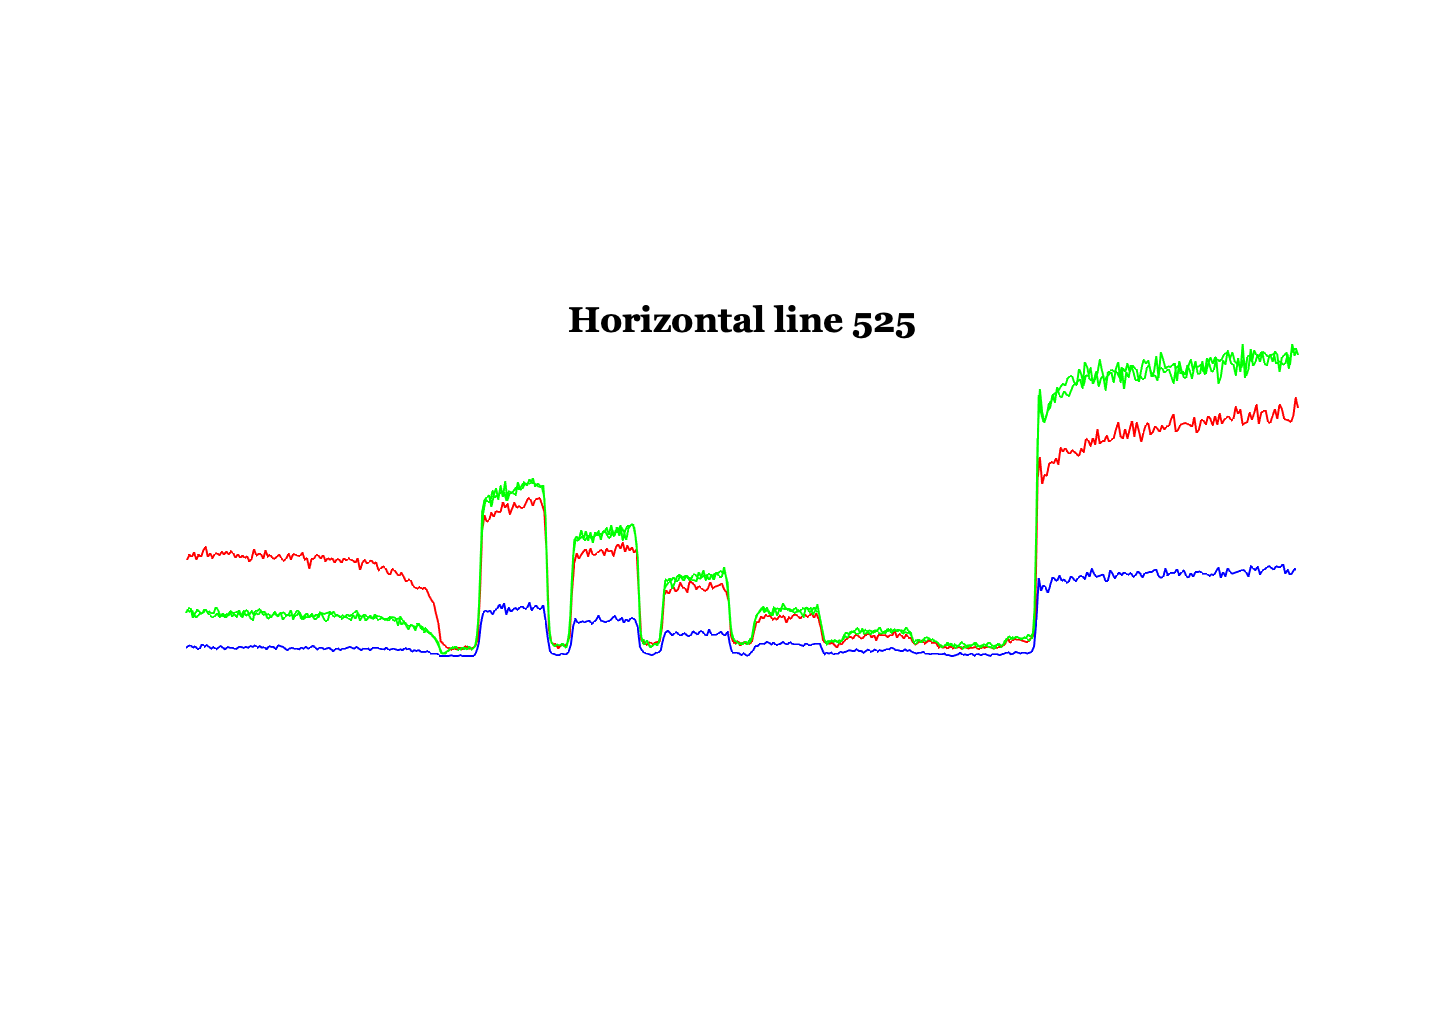

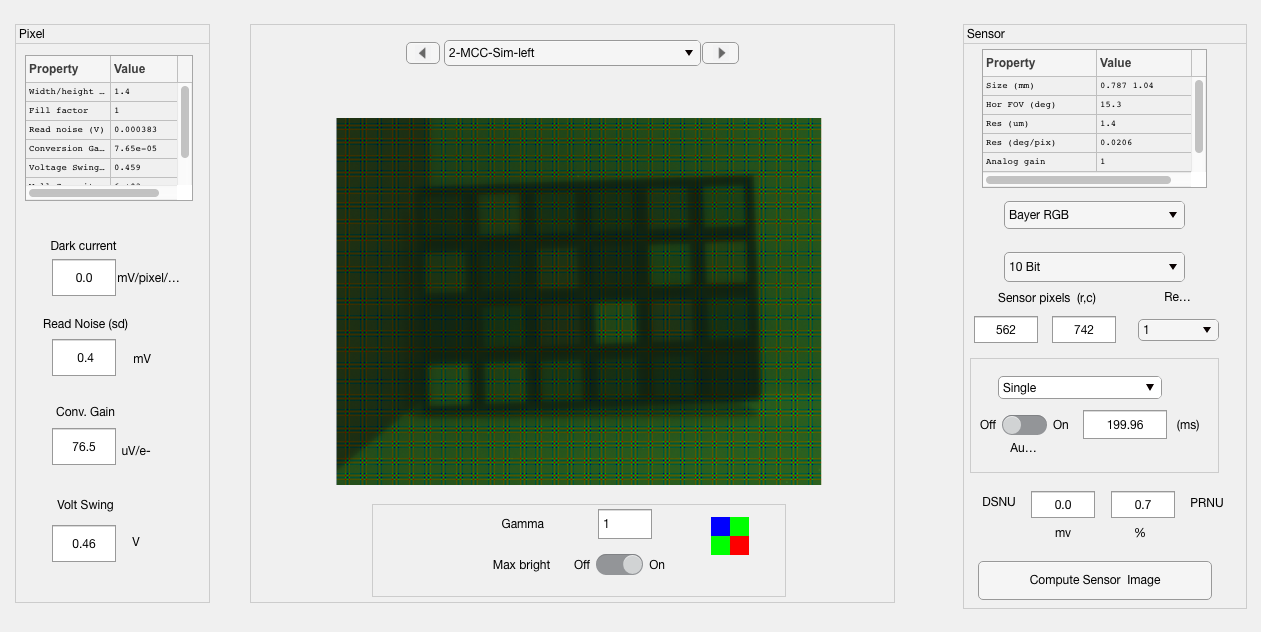

dataDir = '/Users/wandell/Google Drive File Stream/My Drive/Papers/SCIEN/2021 EI Cornell Box (Lyu, Farrell)/Figures/sensorPlot_share';
chdir(dataDir);

chdir('mcc_position');
load('sensorMCCReal.mat','sensorLR');
rect = [853        1589         964         750];
sensorLR = sensorCrop(sensorLR,rect);
sensorWindow(sensorLR);
%{
% Select the crop rectangle and then get it this way.
sensorLS = ieGetObject('sensor');
rect = sensorGet(sensorLS,'roi rect');
%}
lrData = sensorPlot(sensorLR,'dv hline',[1,525],'two lines',true);

load('sensorMCCSim.mat','sensorLS');
rect = [763        1641         741         561];
sensorLS = sensorCrop(sensorLS,rect);
sensorWindow(sensorLS);

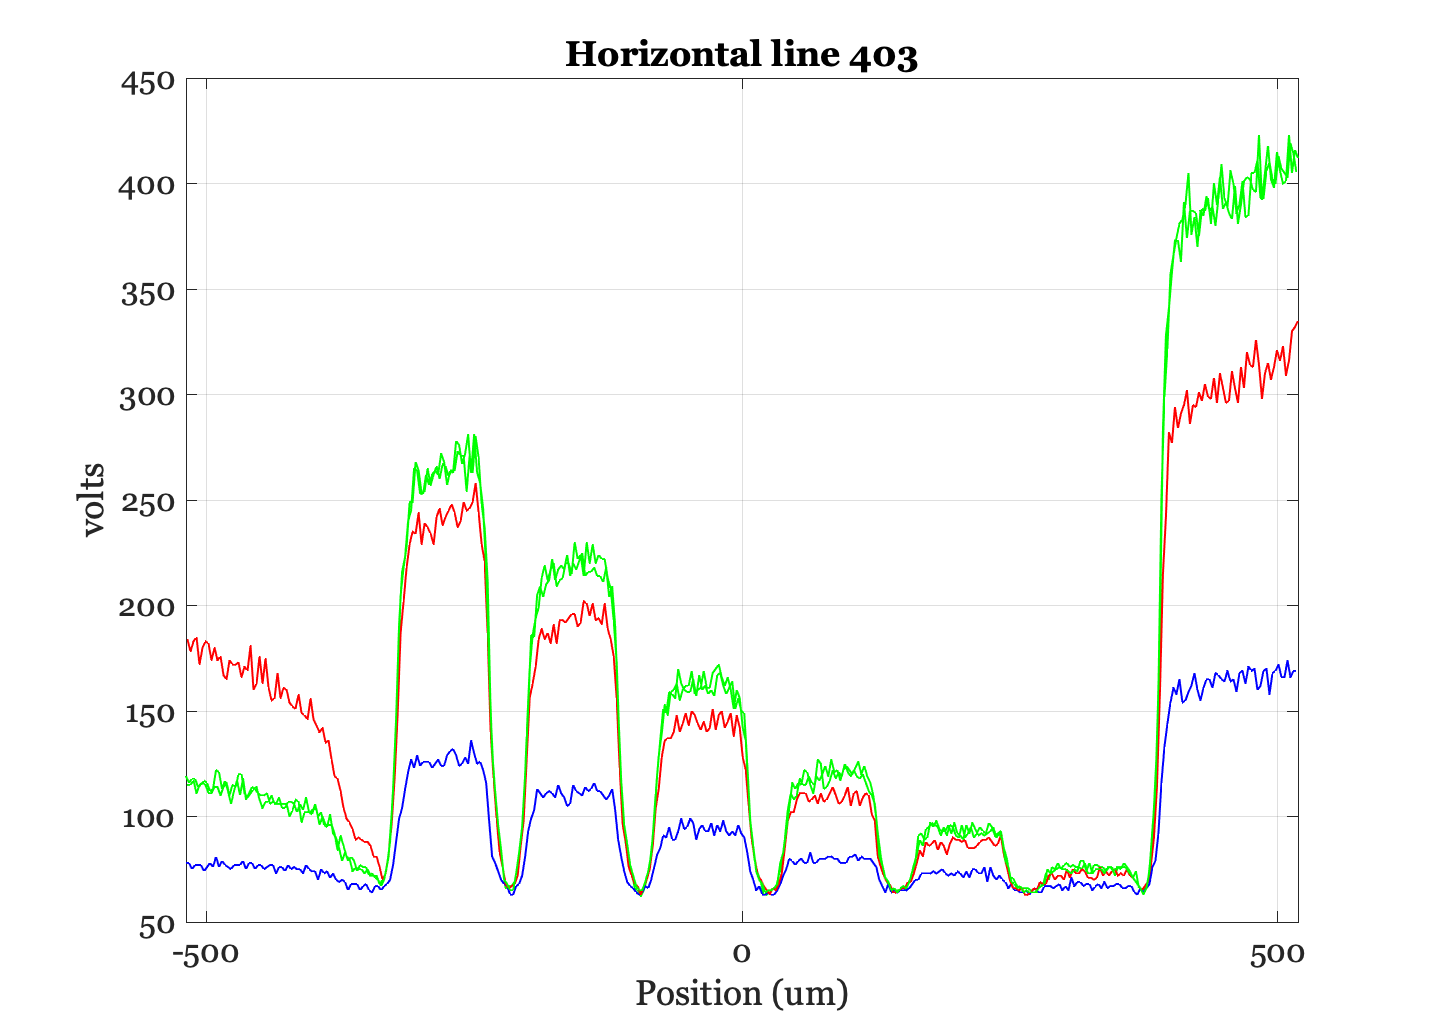

lsData = sensorPlot(sensorLS,'dv hline',[1,403],'two lines',true);

## Repackage the data

D1.x = lrData.pixPos{1};
D1.y = lrData.pixData{1};
D2.x = lsData.pixPos{1};
D2.y = lsData.pixData{1};

## Call ieLineAlign

[p,estY] = ieLineAlign(D1,D2);   % Scale and shift parameters

% Compare
ieNewGraphWin;
plot(D1.x,D1.y,'k--', p(1)*(D2.x - p(2)), D2.y,'r-');

% Equivalent
% plot(D1.x,D1.y,'k--', D1.x, estY,'r-');
%

## PRNU, DSNU calculations

List the files.  These all have an ISO gain of 55 and different exposure times.  They are images of the integrating sphere.  Remember that there is a bad line down the middle, so we choose an ROI just off the center of the image.

dataDir = '/Users/wandell/Google Drive File Stream/My Drive/Data/Cornell box/Camera B/Noise_model/PRNU_DSNU/ISO_55';
chdir(dataDir);
dngFiles = dir('*.dng');

Select the color channel and figure out the ROI and number of pixels in the ROI.

colorChannel = 2;
[sensor, info] = sensorDNGRead(dngFiles(1).name);

%{
% If you need to do this by hand again, you can run this code.
sensorWindow(sensor);
[~,roi] = ieROISelect(sensor);
rect = round(roi.Position);
rect(3) = 20; rect(4) = 20;
%}

% A central position 
rect = [1841  1292  20    20];

% Upper left position 441  419   20    20
sensor = sensorCrop(sensor,rect);
tmp = sensorGet(sensor,'digital values',colorChannel);
nPixels = size(tmp,1);

## Accumulate the raw data

Read the data from the 25 different files.

% Each row is a different pixel.
% Each column is a different exposure duration
% We could average the 5 repeats of the exposure durations

% Matrix of pixels x exposure durations
dv = zeros(nPixels,numel(dngFiles));
eTimes = zeros(numel(dngFiles),1);

for ii=1:numel(dngFiles)
    [sensor, info] = sensorDNGRead(dngFiles(ii).name,'crop',rect);
    dv(:,ii) = sensorGet(sensor,'digital values',colorChannel);
    eTimes(ii) = info.ExposureTime;
end

## Plot a sample of how the digital values increase with exposure time

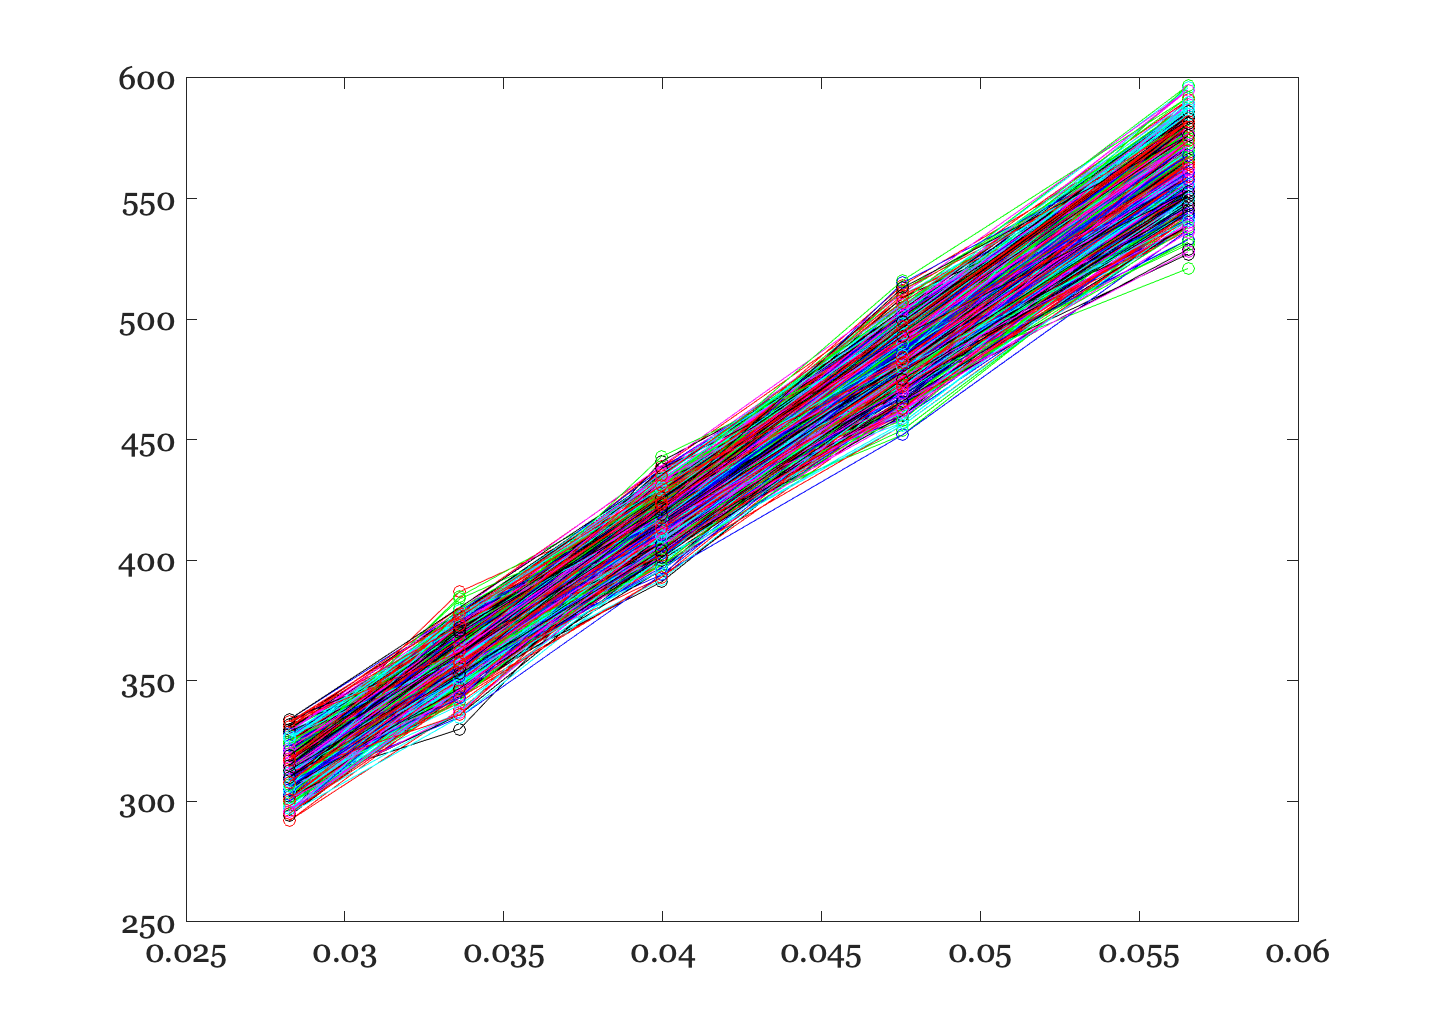

ieNewGraphWin;
plot(eTimes,dv((1:2:nPixels),:),'o-')

xlabel('Time (sec)'); ylabel('DV')
title('All the individual measurements')

## Average across the five exposures

nExposures = 5;
nPixels    = size(dv,1);
meanDV = zeros(nPixels,nExposures);
for ii=1:nExposures
    lst = (eTimes == eTimes(ii));
    meanDV(:,ii) = dv*lst(:)/nExposures;
end
eTimeList = unique(eTimes)

eTimeList =     0.0282
    0.0336
    0.0400
    0.0476
    0.0565


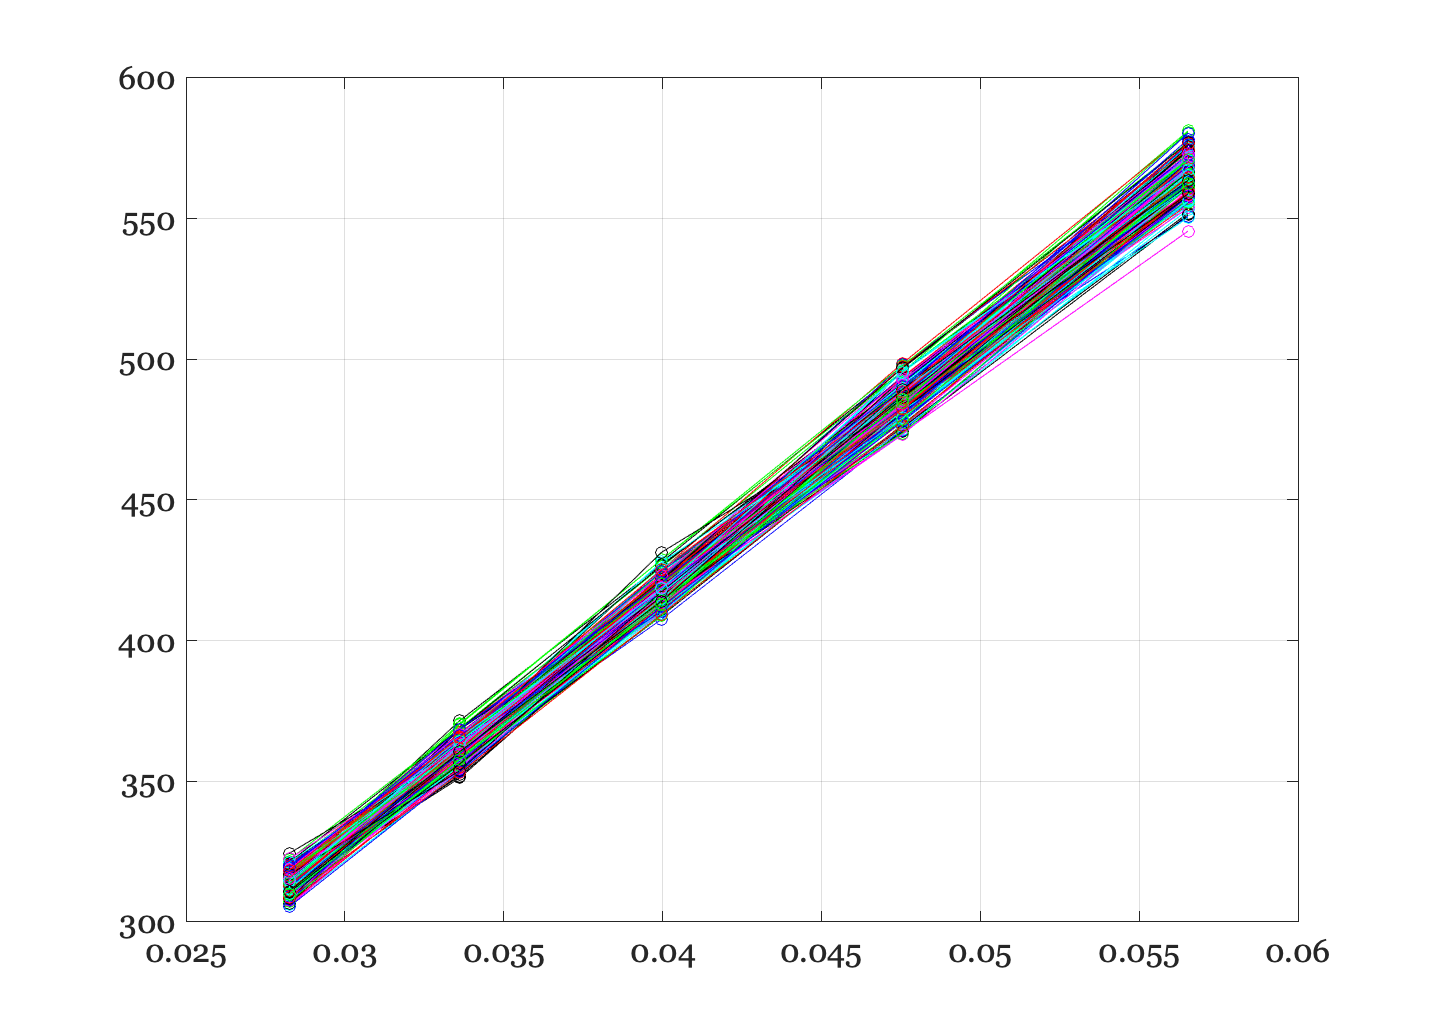


ieNewGraphWin;
% imagesc(meangDV)
plot(eTimeList,meanDV(1:nPixels,:),'o-')
grid on;

title('Average of 5 measurements')
xlabel('Time (sec)'); ylabel('DV')

## Fit the line

p = zeros(nPixels,2);
for ii=1:nPixels
    p(ii,:) = polyfit(eTimeList,meanDV(ii,:),1);
end

meanSlope  = mean(p(:,1));
meanOffset = mean(p(:,2));
fprintf('PRNU %.3f percent\n', (std(p(:,1))/meanSlope)*100);   % STD of the slope as a percent

1.894 PRNU (percent)


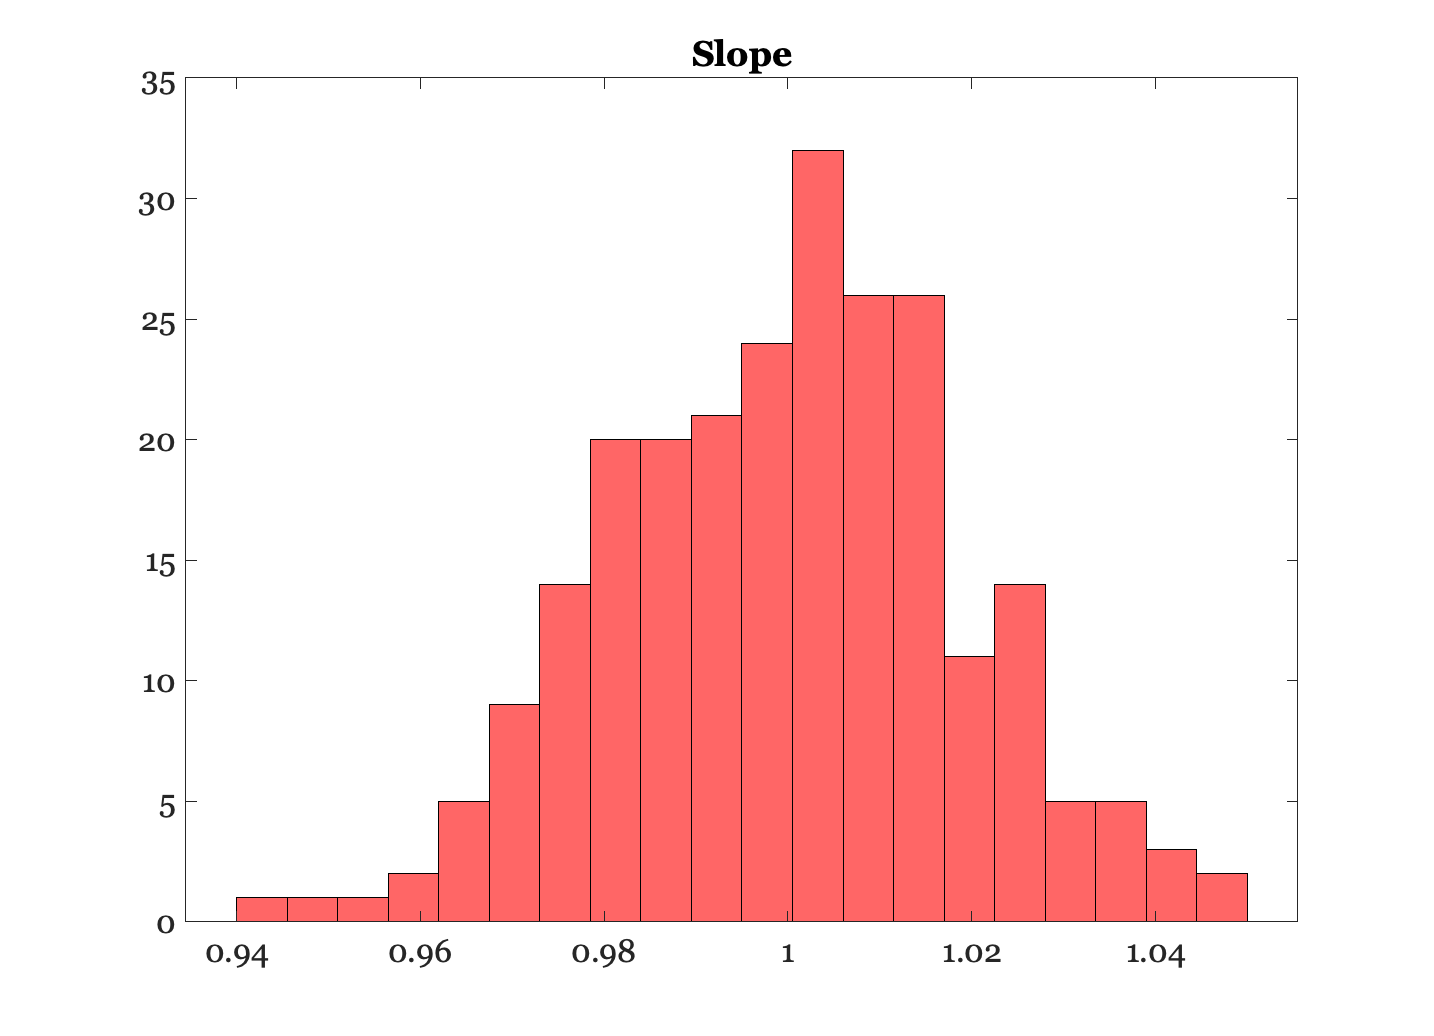


ieNewGraphWin;
histogram((p(:,1)/meanSlope),20)
title('Slope');

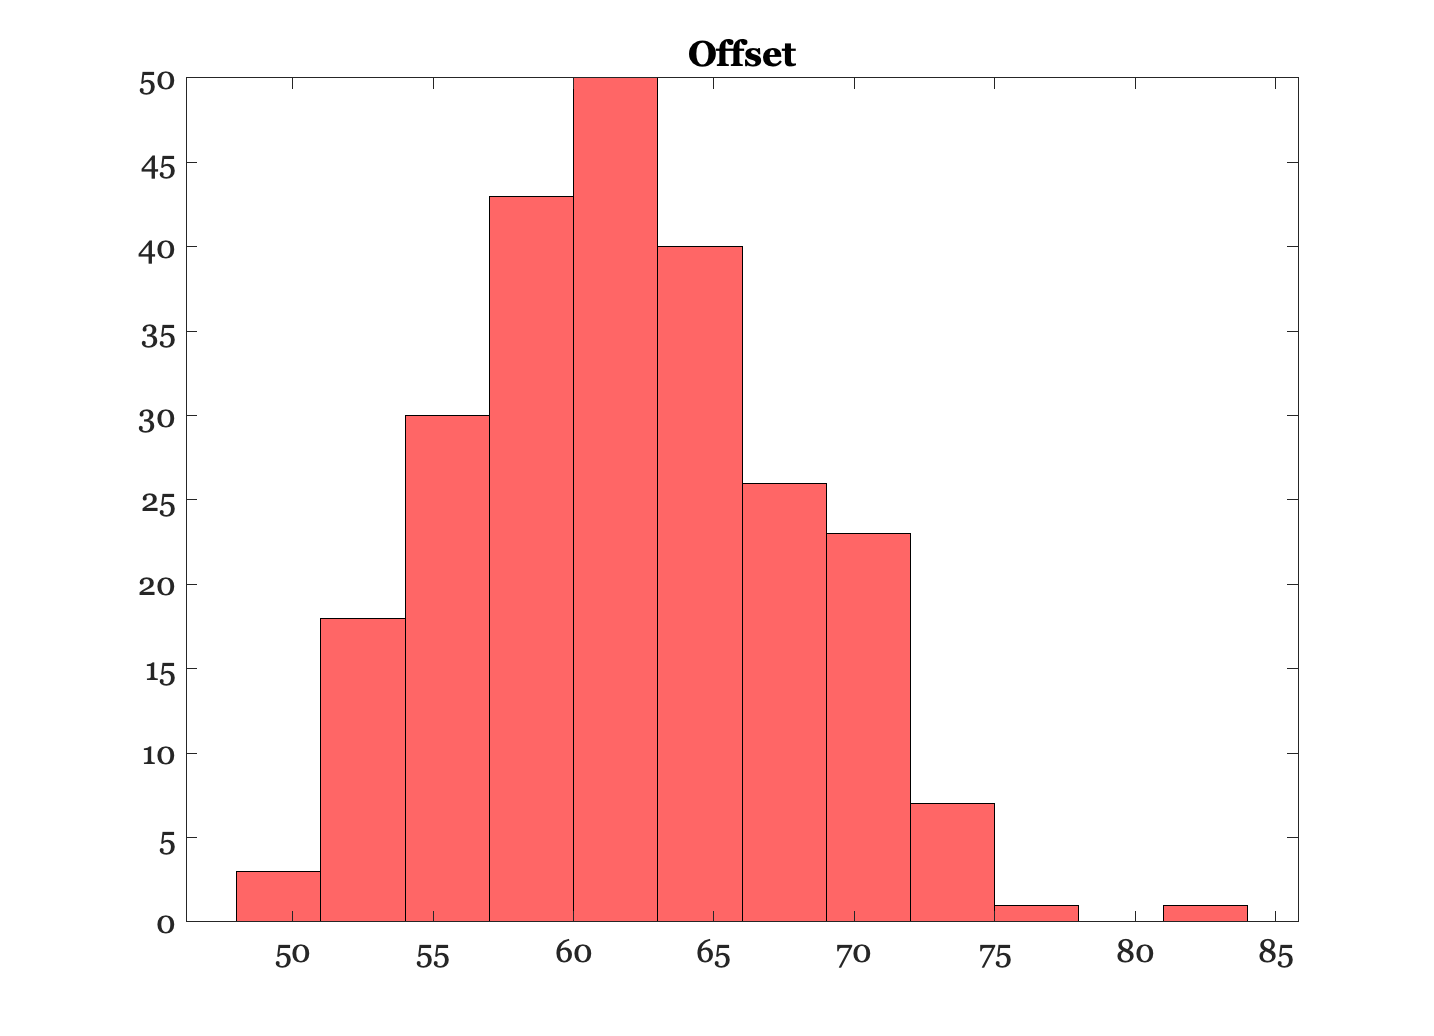


ieNewGraphWin;
histogram(p(:,2))
title('Offset')


fprintf('DSNU %.3f digital values \n',std(p(:,2)))   %  STD of the offset

5.681 DSNU



vPerDV = sensorGet(sensor,'pixel voltage swing')/2^12;
DSNUVolts = std(p(:,2))*vPerDV % About 0.6 mV on a total of 450 mV

DSNUVolts = 6.3666e-04